clear
close all
clc

**Trayectoria 3: **

X = [-6 a 6]

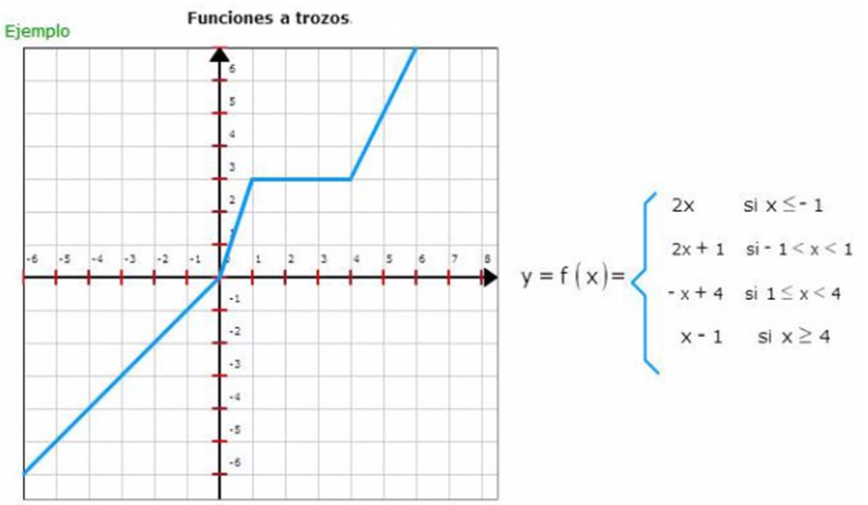

Iniciaremos la codificación de la trayectoria declarando el vector de tiempo en el que realizaremos las simulación, en dónde tf es el tiempo total de simulación y ts es el tiempo de muestro en segundos. 


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% TIEMPO %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Definimos el vector de tiempo

tf = 8;        % Tiempo final
ts = 0.1;       % Tiempo de muestreo en segundos (s)
t = 0.1:ts:tf;   % Vector de tiempo
N = length(t);  % Muestras


Para este caso, partiremos del punto inferior de la gráfica, es decir, en la coordenada [-6, -6, 0].

%%%%%%%%%%%%%%%%%%%%%%%% CONDICIONES INICIALES %%%%%%%%%%%%%%%%%%%%%%%%%%%%

x1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje x) en metros (m)
y1 = zeros (1,N+1);  % Posición en el centro del eje que une las ruedas (eje y) en metros (m)
phi = zeros(1, N+1); % Orientacion del robot en radianes (rad)

x1(1) = -6;    % Posicion inicial eje x
y1(1) = -6;   % Posicion inicial eje y
phi(1) = 0;   % Orientacion inicial del robot

%%%%%%%%%%%%%%%%%%%%%%%%%%%% PUNTO DE CONTROL %%%%%%%%%%%%%%%%%%%%%%%%%%%%

hx = zeros(1, N+1);  % Posicion en el punto de control (eje x) en metros (m)
hy = zeros(1, N+1);  % Posicion en el punto de control (eje y) en metros (m)

hx(1) = x1(1); % Posicion en el punto de control del robot en el eje x
hy(1) = y1(1); % Posicion en el punto de control del robot en el eje y


Ahora bien, identifiquemos que en esta trayectoria contamos con 4 segmentos, en donde habra 4 rotaciones y 4 avances en recta, es decir, tendremos un total de 8 segmentos o movimientos. Considerando esto, crearemos 8 sub-vectores para velocidad lineal y angular y los concatenaremos al final para lograr el momimiento completo.

%%%%%%%%%%%%%%%%%%%%%% VELOCIDADES DE REFERENCIA %%%%%%%%%%%%%%%%%%%%%%%%%%
n = floor(N/8); 

**1. Primer movimiento: Rotación: **A simple vista, podemos darnos cuenta que nuestro robot en primer instante necesita rotar 45 grados (pi/4). Esto lo podemos comprobar utilizando funciones trigonometricas: 

%%Rotamos 45 grados
u_a= zeros(1, n); %DADO QUE SOLO DESEAMOS ROTAR, LA VELOCIDAD LIENAL ES CERO 
w_a = pi/4*ones(1, n ); 

angle = pi/4; %El angulo al que se encuentra el robot


**2. Segundo movimiento: Avance en recta: **Ahora que hemos rotado, debemos avanzar cierta cantidad de unidades. Podemos conocer esta cantidad de unidades de manera precisa aplicando un teorema de pitagoras, ya que en esta primera trayectoria se forma un triangulo rectangulo cuyos catetos son de 6 unidades. Dicho esto, tenemos que la distancia a avanzar sera de sqrt(6^2+6^2) -> sqrt(72).

u_b = sqrt(72)*ones(1,n);
w_b = zeros(1,n); %LA VELOCIDAD ANGULAR DEBE SER CERO

**3. Tercer movimiento: Rotación: **Nuevamente, podemos realizar la rotación de un nuevo ángulo, el cuál podemos conocer su medida gracias a las funciones trigonometricas. Aplicando esto, tendemos que este ángulo sería de: 

angle_setpoint = acot(1/3) %Angulo al que se debe mover

angle_setpoint = 1.2490

No obstante, debemos considerar que previamente ya rotamos pi/4: 

angle = angle_setpoint-pi/4; %Rotación que debe realizar
u_c = zeros(1,n); 
w_c = angle*ones(1,n); 

**4. Cuarto movimiento: Avance en recta: **Aplicando un teorema de pitagoras podemos saber que debemos avanzar exactamente sqrt(10) unidades: 

%Avanzamos srqt(10)
u_d = sqrt(10)*ones(1,n);
w_d = zeros(1,n);

**5. Quinto movimiento: Rotación: **Ahora, debemos realizar una rotación hacia el sentido contrario (negativo) de tal forma que nos ubiquemos en 0 grados. Para lograr esto, rotaremos de manera negativa el ángulo al que nos encontramos: 

u_e = zeros(1,n);
w_e = -angle_setpoint*ones(1,n);

**6. Sexto movimiento: Avance en recta: **Avanzamos 4 unidades: 

u_f = 4*ones(1,n);
w_f = zeros(1,n);

**7. Septimo movimiento: Rotación: **Para nuestro penultimo movimiento deberemos realizar una rotación de *x *grados. Podemos conocer este ángulo aplicando funciones trigonometricas: 

angle = acot(2/4); 

angle = 1.1071

u_g = zeros(1,n);
w_g = angle*ones(1,n);

**8. Octavo movimiento: Avance en recta**

u_h = sqrt(20)*ones(1,n);
w_h = zeros(1,n);

Finalmente, creamos el vector de velocidad angular y lineal realizando la concatenación de los declarados previamente: 

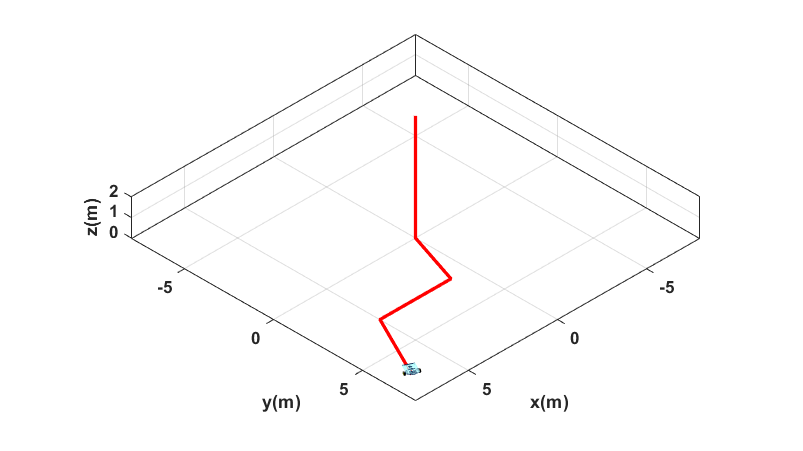

%Concatenamos
u = [u_a, u_b, u_c, u_d, u_e, u_f, u_g, u_h];
w = [w_a, w_b, w_c, w_d, w_e, w_f, w_g, w_h];
%%%%%%%%%%%%%%%%%%%%%%%%% BUCLE DE SIMULACION %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

for k=1:N 
    
    phi(k+1)=phi(k)+w(k)*ts; % Integral numérica (método de Euler)
    
    %%%%%%%%%%%%%%%%%%%%% MODELO CINEMATICO %%%%%%%%%%%%%%%%%%%%%%%%%
    
    xp1=u(k)*cos(phi(k+1)); 
    yp1=u(k)*sin(phi(k+1));

    x1(k+1)=x1(k) + xp1*ts ; % Integral numérica (método de Euler)
    y1(k+1)=y1(k) + yp1*ts ; % Integral numérica (método de Euler)
    
    
    % Posicion del robot con respecto al punto de control
    hx(k+1)=x1(k+1); 
    hy(k+1)=y1(k+1);

end

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% SIMULACION VIRTUAL 3D %%%%%%%%%%%%%%%%%%%%%%%%%%%%

% a) Configuracion de escena

scene=figure;  % Crear figura (Escena)
set(scene,'Color','white'); % Color del fondo de la escena
set(gca,'FontWeight','bold') ;% Negrilla en los ejes y etiquetas
sizeScreen=get(0,'ScreenSize'); % Retorna el tamaño de la pantalla del computador
set(scene,'position',sizeScreen); % Congigurar tamaño de la figura
camlight('headlight'); % Luz para la escena
axis equal; % Establece la relación de aspecto para que las unidades de datos sean las mismas en todas las direcciones.
grid on; % Mostrar líneas de cuadrícula en los ejes
box on; % Mostrar contorno de ejes
xlabel('x(m)'); ylabel('y(m)'); zlabel('z(m)'); % Etiqueta de los eje

view([135 35]); % Orientacion de la figura
axis([-8 8 -8 8 0 2]); % Ingresar limites minimos y maximos en los ejes x y z [minX maxX minY maxY minZ maxZ]

% b) Graficar robots en la posicion inicial
scale = 4;
MobileRobot_5;
H1=MobilePlot_4(x1(1),y1(1),phi(1),scale);hold on;

% c) Graficar Trayectorias
H2=plot3(hx(1),hy(1),0,'r','lineWidth',2);

% d) Bucle de simulacion de movimiento del robot

step=1; % pasos para simulacion

for k=1:step:N

    delete(H1);    
    delete(H2);
    
    H1=MobilePlot_4(x1(k),y1(k),phi(k),scale);
    H2=plot3(hx(1:k),hy(1:k),zeros(1,k),'r','lineWidth',2);
    
    pause(ts);

end

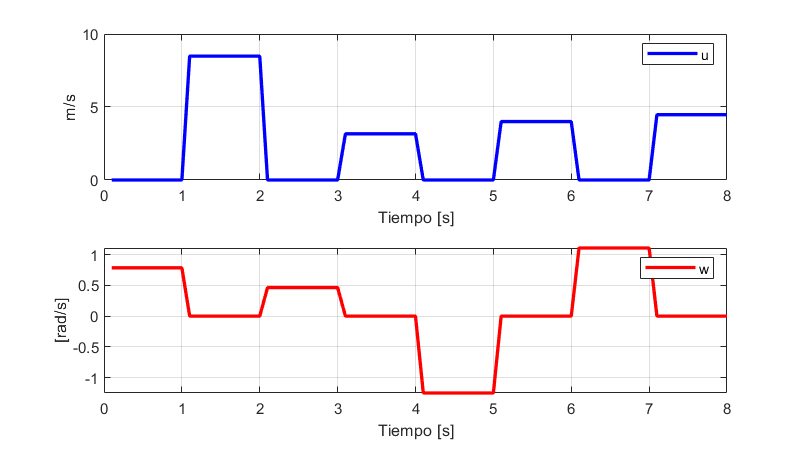


%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Graficas %%%%%%%%%%%%%%%%%%%%%%%%%%%%
graph=figure;  % Crear figura (Escena)
set(graph,'position',sizeScreen); % Congigurar tamaño de la figura
subplot(211)
plot(t,u,'b','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('m/s'),legend('u');
subplot(212)
plot(t,w,'r','LineWidth',2),grid('on'),xlabel('Tiempo [s]'),ylabel('[rad/s]'),legend('w');